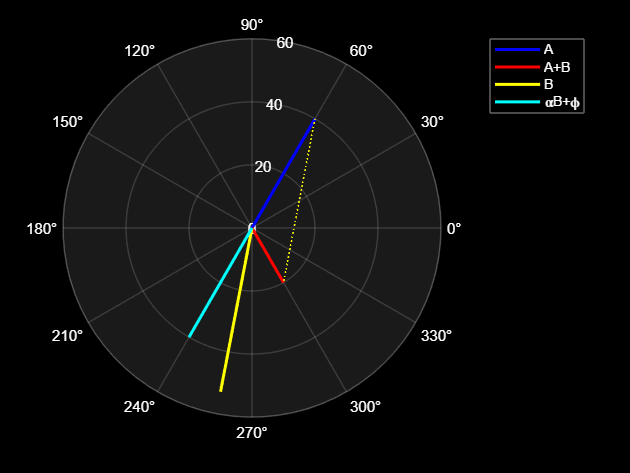

mass = 0

angle = 340.8934

A = [pi/3, 40];
AB = [-pi/3, 20];
[mass, angle] = compute_correction(A, AB, 0, 0, false)

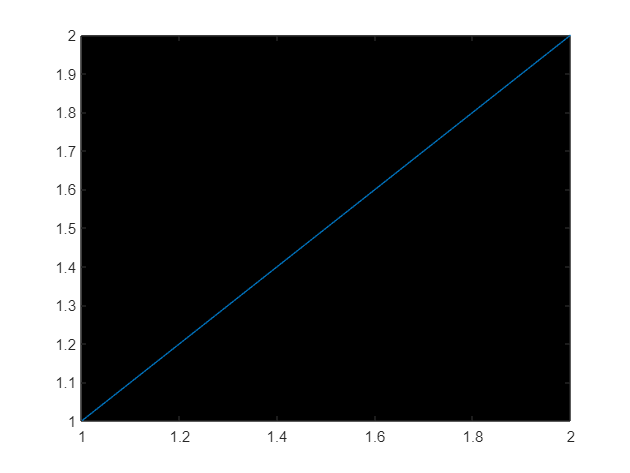

f  = figure;
plot([1 2], [1 2])
%set(gca, 'InvertHardCopy', 'off'); 
set(gca,'Color',[0 0 0]); % RGB values [0 0 0] indicates black color


% clear arduino;

    %connect to serial, re-run untill light tunrs on
    arduino = serialport("COM17", 115200);




num_data_points = 400;

    %set up data struct to read
    arduino.UserData = struct("Data",zeros(num_data_points,3),"Count",1, "Points", num_data_points, "Running", true);
    flush(arduino);
    serial_command(arduino, num_data_points/10);
    configureTerminator(arduino,"CR");
    flush(arduino);
    
    
    configureCallback(arduino,"terminator", @read_data);
    while(arduino.UserData.Running)
    %disp(arduino.UserData.Count)
    pause(0.01)
    end

    disp("done")

done




    arduino.UserData.Data

ans =    11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300
   11.1100   22.2200   33.3300


configureCallback(arduino, "off");

Unrecognized function or variable 'BasicClass'.

     function read_data(src, ~)

    % Read the ASCII data from the serialport object.

    data = readline(src);

    data = split(data);
    data = str2double(data);

     %Convert the string data to numeric type and save it in the UserData
     %property of the serialport object.
     src.UserData.Data(src.UserData.Count,:) = [data(1) data(2) data(3)];
 
     % Update the Count value of the serialport object.
     src.UserData.Count = src.UserData.Count + 1;

  
     % If 1001 data points have been collected from the Arduino, switch off the
     % callbacks and plot the data.
         if src.UserData.Count > src.UserData.Points
            configureCallback(src, "off");
            src.UserData.Running = false;

            
         end
    end
